addpath('Classes')
addpath('Simulink Models')
addpath('Functions')

%Make sure symprefs are set correctly for this script
sympref('MatrixWithSquareBrackets',true);
sympref('AbbreviateOutput', false);
sympref('FloatingPoint',true);
sympref('TypesetOutput',true);


# Output Sliding Mode Control Research Script

%Create a variable definitions object if one does not already exist. 
if (~exist('VDefs', 'var')) 

    VDefs = Var_Defs;  %Create an object of the class Var_Defs

end 

%Create a u-joint Kinematics object if one does not already exist. 
if (~exist('UJ_Knmtcs', 'var')) 

    UJ_Knmtcs = UJ_Knmtcs(VDefs); %Create an object of the class UJ_Knmtcs
    UJ_Knmtcs.derive_all; %Run all of its derivation functions

end 

%Create a ball-plate kinematics object if one does not already exist. 
if (~exist('BP_Knmtcs', 'var')) 

    BP_Knmtcs = BP_Knmtcs(VDefs, UJ_Knmtcs); %Create an object of the class BP_Knmtcs
    BP_Knmtcs.Derive_Both; %Derive all the kinematic equations for the ball-plate system
end 

%Create a ball-plate kinetics object if one does not already exist. 
if (~exist('BP_Kinetics', 'var')) 

    BP_Kinetics = BP_Kinetics(VDefs, UJ_Knmtcs, BP_Knmtcs); %Create an object of the class BP_Kinetics
    BP_Kinetics.Derive_NL_EOMs; %Derive the nonlinear equations of motion for the ball-plate system
    BP_Kinetics.Num_Params_n_Assumptions; %Input numerical parameters and assumptions

end 


%Create a linearized EOMs object if one does not already exist. 
if (~exist('Lnrzed_EOMs', 'var')) 

    Lnrzed_EOMs = Lnrzed_EOMs(VDefs, BP_Kinetics); %Create an object of the class Lnrzed_EOMs
    Lnrzed_EOMs.Derive_8th_Ordr_Lin_Sys;

end 

%Create a nonlinear decoupled EOMs object if one does not already exist. 
if (~exist('NL_Dcpld_EOMs', 'var')) 

    NL_Dcpld_EOMs = NL_Dcpld_EOMs(VDefs, BP_Kinetics); %Create an object of the class NL_Dcpld_EOMs
    NL_Dcpld_EOMs.Num_Params;

end

%Define a few symbolic variables to be used
syms lambda_1 lambda_2 S_1 S_2 S_dot_1 S_dot_2 u_1 u_2 u_hat_1 u_hat_2 K_s


## System 1 - x direction

### Sliding Surface for global x location of the ball 


$$\begin{array}{l}

S_1 = e_{\dot{x}} + \lambda_1 \, e_x\\

\end{array}

$$


e_x = VDefs.x_s - VDefs.x;
e_x_dot = VDefs.x_dot_s - VDefs.x_dot;
S1_eqn = S_1 ==  e_x_dot + lambda_1*(e_x)

$$S1\_eqn = S_{1}={\dot{x}}_{s}-\dot{x}-\lambda_{1}\,\left(x-x_{s}\right)$$

xdd = rhs(isolate(NL_Dcpld_EOMs.Num_SumMBall_x, VDefs.x_ddot));

In the sum of moments for the ball, call $sin(\beta)~u_1$. 

xdd = subs(xdd, sin(VDefs.beta), u_1)

$$xdd = 0.7143\,{\dot{\beta }}^{2}\,x+7.0071\,u_{1}-0.1113\,\ddot{\beta }$$

Sd1_eqn = S_dot_1 == VDefs.x_ddot_s - xdd + lambda_1*(e_x_dot)

$$Sd1\_eqn = {\dot{S}}_{1}=0.1113\,\ddot{\beta }-7.0071\,u_{1}+{\ddot{x}}_{s}-\lambda_{1}\,\left(\dot{x}-{\dot{x}}_{s}\right)-0.7143\,{\dot{\beta }}^{2}\,x$$

### Nullifying $\mathbf{sin(\beta)}$ Input 

Finding the input, $u_1(\beta) = sin(\beta)$, required to zero out the derivative of the sliding surface. Allows us to determine wether or not the sliding surface is attractive given the angular constraints (if nullifying input exceeds the constraints, it may not be possible to make the surface attractive). 

u_hat_1_eqn = u_hat_1 == rhs(isolate(subs(Sd1_eqn, S_dot_1, 0),u_1))

$$u\_hat\_1\_eqn = {\hat{u}}_{1}=0.0159\,\ddot{\beta }+0.1427\,{\ddot{x}}_{s}-0.1427\,\lambda_{1}\,\left(\dot{x}-{\dot{x}}_{s}\right)-0.1019\,{\dot{\beta }}^{2}\,x$$


%Test Nullifying Input
simplify(subs(rhs(Sd1_eqn ), u_1, rhs(u_hat_1_eqn)))

$$ans = 0$$

### Lyapunov Function and Switching Law


$$\begin{array}{l}

V_1 = \frac{S_1^^2}{2}\\

\dot{V}_1 = S_1 \, \dot{S}_1

\end{array}$$


Vd1 = S_1*rhs(Sd1_eqn)

$$Vd1 = -S_{1}\,\left(7.0071\,u_{1}-0.1113\,\ddot{\beta }-{\ddot{x}}_{s}+\lambda_{1}\,\left(\dot{x}-{\dot{x}}_{s}\right)+0.7143\,{\dot{\beta }}^{2}\,x\right)$$


b_S1d = double(equationsToMatrix(rhs(Sd1_eqn), u_1)) %Input matrix for u_1 in S1dot equation

b_S1d = -7.0071


switching_law1 = -K_s/b_S1d*sign(S_1) %

$$switching\_law1 = 0.1427\,K_{s}\,\mathrm{sign}\left(S_{1}\right)$$

## System 2 - y direction

### Sliding Surface for global x location of the ball 


$$\begin{array}{l}

S_2 = e_{\dot{y}} + \lambda_2 \, e_y\\

\end{array}

$$


e_y = VDefs.y_s - VDefs.y;
e_y_dot = VDefs.y_dot_s - VDefs.y_dot;
S2_eqn = S_2 ==  e_y_dot + lambda_2*(e_y)

$$S2\_eqn = S_{2}={\dot{y}}_{s}-\dot{y}-\lambda_{2}\,\left(y-y_{s}\right)$$

ydd = rhs(isolate(NL_Dcpld_EOMs.Num_SumMBall_y, VDefs.y_ddot));

In the sum of moments for the ball, call $sin(\gamma)~u_2$. 

ydd = subs(ydd, sin(VDefs.gamma), u_2)

$$ydd = 0.7143\,{\dot{\gamma }}^{2}\,y-7.0071\,u_{2}+0.1113\,\ddot{\gamma }$$

Sd2_eqn = S_dot_2 == VDefs.y_ddot_s - ydd + lambda_2*(e_y_dot)

$$Sd2\_eqn = {\dot{S}}_{2}=7.0071\,u_{2}-0.1113\,\ddot{\gamma }+{\ddot{y}}_{s}-\lambda_{2}\,\left(\dot{y}-{\dot{y}}_{s}\right)-0.7143\,{\dot{\gamma }}^{2}\,y$$

### Nullifying $\mathbf{sin(\gamma)}$ Input 

Finding the input, $u_2(\gamma) = sin(\gamma)$, required to zero out the derivative of the sliding surface. Allows us to determine wether or not the sliding surface is attractive given the angular constraints (if nullifying input exceeds the constraints, it may not be possible to make the surface attractive). 

u_hat_2_eqn = u_hat_2 == rhs(isolate(subs(Sd2_eqn, S_dot_2, 0),u_2))

$$u\_hat\_2\_eqn = {\hat{u}}_{2}=0.0159\,\ddot{\gamma }-0.1427\,{\ddot{y}}_{s}+0.1427\,\lambda_{2}\,\left(\dot{y}-{\dot{y}}_{s}\right)+0.1019\,{\dot{\gamma }}^{2}\,y$$


%Test Nullifying Input
simplify(subs(rhs(Sd2_eqn ), u_2, rhs(u_hat_2_eqn)))

$$ans = 0$$

### Lyapunov Function and Switching Law


$$\begin{array}{l}

V_2 = \frac{S_2^^2}{2}\\

\dot{V}_2 = S_2 \, \dot{S}_2

\end{array}$$


Vd2 = S_2*rhs(Sd2_eqn)

$$Vd2 = -S_{2}\,\left(0.1113\,\ddot{\gamma }-7.0071\,u_{2}-{\ddot{y}}_{s}+\lambda_{2}\,\left(\dot{y}-{\dot{y}}_{s}\right)+0.7143\,{\dot{\gamma }}^{2}\,y\right)$$


b_S2d = double(equationsToMatrix(rhs(Sd2_eqn), u_2)) %Input matrix for u_2 in S2dot equation

b_S2d = 7.0071


switching_law2 = -K_s/b_S2d*sign(S_2)

$$switching\_law2 = -0.1427\,K_{s}\,\mathrm{sign}\left(S_{2}\right)$$

## Desired Trajectory in x and y

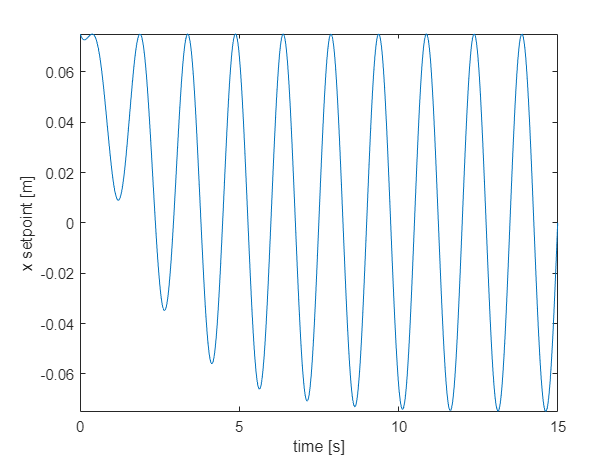

%Ideal trajectory parameters
r_sim = .15; % radius of trajectory [m] Touch screen is about 30 cm wide
% freq = 1/9; %rotations per second: 1/9 for octofolium is about as fast as it gets
% freq = 1/6; %rotations per second:  1/6 for quadrifolium is about as fast as it gets
freq = 1/3;
omega_sim =  2*pi*freq; %angular frequency of circular trajectory 


%Specify initial conditions and compute initial outputs
x_0 = 1/2*[r_sim; 0; 0; 0; r_sim; 0; 0; 0]; %As if the ball was at rest in the center of the plate - the control objective of any regulator designed for the system


%Ideal trajectory symfuns
%Figure 8
% des_traj_sym_x(VDefs.t) = r_sim*sin(omega_sim*VDefs.t)*cos(omega_sim*VDefs.t);
% des_traj_sym_y(VDefs.t) = r_sim*sin(omega_sim*VDefs.t);

%Simple STAY AT THE ICs SETPOINT for tuning inner angular loops
% des_traj_sym_x(VDefs.t) = x_0(1) + 0*VDefs.t;
% des_traj_sym_y(VDefs.t) = x_0(5) + 0*VDefs.t;

%Rose curve specified by k
n = 1;
d = 1;
k = n/d
des_traj_sym_y1(VDefs.t) = r_sim*cos(k*omega_sim*VDefs.t)*cos(omega_sim*VDefs.t);
des_traj_sym_y2(VDefs.t) = r_sim*cos(k*omega_sim*VDefs.t)*sin(omega_sim*VDefs.t);


%Overlay first order smoothing functions
Tau = 2; %Time constant for first order response (3 has been working well at the 1.3 Hz)


%Trajectory symfuns with first order smoothing overlayed and a smooth transition from the
%initial conditions
des_traj_sym_x(VDefs.t) = des_traj_sym_x(VDefs.t)*(1-exp(-VDefs.t/Tau)) + x_0(1)*exp(-VDefs.t/Tau);
des_traj_sym_y(VDefs.t) = des_traj_sym_y(VDefs.t)*(1-exp(-VDefs.t/Tau)) + x_0(5)*exp(-VDefs.t/Tau);

figure
fplot(des_traj_sym_x) 
xlim([0 2*pi/omega_sim*5]); 
ylabel('x setpoint [m]')
xlabel('time [s]')

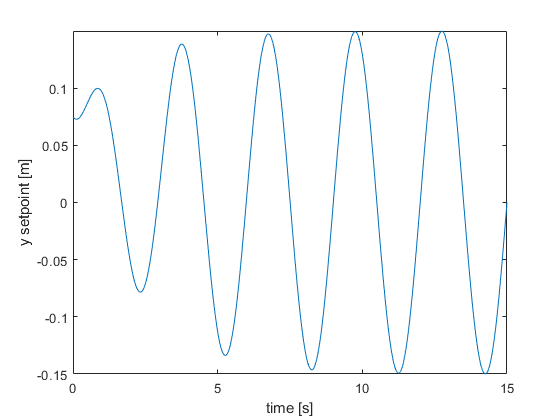


figure
fplot(des_traj_sym_y) 
xlim([0 2*pi/omega_sim*5]); 
ylabel('y setpoint [m]')
xlabel('time [s]')


%Trajectory's derivatives
des_traj_sym_dot_x(VDefs.t) = diff(des_traj_sym_x(VDefs.t),VDefs.t);
des_traj_sym_dot_y(VDefs.t) = diff(des_traj_sym_y(VDefs.t),VDefs.t);
des_traj_sym_ddot_x(VDefs.t) = diff(des_traj_sym_x(VDefs.t),VDefs.t,2);
des_traj_sym_ddot_y(VDefs.t) = diff(des_traj_sym_y(VDefs.t),VDefs.t,2);

%x_s_vec and y_s_vec
des_traj_sym_x = [des_traj_sym_x;des_traj_sym_dot_x;des_traj_sym_ddot_x];
des_traj_sym_y = [des_traj_sym_y;des_traj_sym_dot_y;des_traj_sym_ddot_y];

## Numerical Control Parameters


%Choose numerical lambdas 
lambda_1_num = 1/10; %1/10 seemed good
lambda_2_num = lambda_1_num;

%Max torque
Tmax = VDefs.Tmax; % [Nm] Comes from rated torque of Scott's motors and the gear ratio assumption
%Tmax = 1000;

%Max angle
Angle_max = deg2rad(20) %Used to saturate the requested angular setpoint for the inner loop

Angle_max = 0.3491


%Switching gain
K_switch = sin(Angle_max)/7; %Not a saturation on the input, only aggressiveness tuning /5 was latest working divisor with 1/6 Hz. 1/10 works somewhat with 1/3 Hz

%Boundary layer size
S_BL_value = 0.1; %.05 seemed to be pretty good for the 1/3 hz frequency - 0.1 worked well with 1/6 Hz
%S_BL_value = 1000;

%Boundary Layer Gain
%BL_gain = (K_switch)/S_BL_value; %To prevent fast switches at the border of the boundary layer, need to have the cuttoff angle be equal to the switching angle
%Gain in the BL is then coupled to the size of the boundary layer. 
BL_gain = 0.5; %0.1 worked well with 1/6 Hz

## Inner Loop Controller Design

syms T_tilde_beta T_tilde_gamma s

%Compute the ball-disturbance rejecting feed-forward torque
betadd_lin_eqn = VDefs.beta_ddot == Lnrzed_EOMs.Lin_EOMs(4) %Get the linear model of beta ddot

$$betadd\_lin\_eqn = \ddot{\beta }=20.2622\,x+31.3281\,\beta +9.1798\,T_{\beta }$$

x_coeff = equationsToMatrix(rhs(betadd_lin_eqn),VDefs.x);
T_hat_beta = -x_coeff*VDefs.x/Lnrzed_EOMs.B(4,1)

$$T\_hat\_beta = -2.2072\,x$$


%Test disturbance rejecting torque
betadd_lin_eqn = subs(betadd_lin_eqn, VDefs.T_beta, T_hat_beta + T_tilde_beta)

$$betadd\_lin\_eqn = \ddot{\beta }=31.3281\,\beta +9.1798\,{\tilde{T}}_{\beta }$$


%Compute the ball-disturbance rejecting feed-forward torque
gammadd_lin_eqn = VDefs.gamma_ddot == Lnrzed_EOMs.Lin_EOMs(8) %Get the linear model of gamma ddot

$$gammadd\_lin\_eqn = \ddot{\gamma }=-20.2622\,y+31.3281\,\gamma +9.1798\,T_{\gamma }$$

y_coeff = equationsToMatrix(rhs(gammadd_lin_eqn),VDefs.y);
T_hat_gamma = -y_coeff*VDefs.y/Lnrzed_EOMs.B(8,2)

$$T\_hat\_gamma = 2.2072\,y$$


%Test disturbance rejecting torque
gammadd_lin_eqn = subs(gammadd_lin_eqn, VDefs.T_gamma, T_hat_gamma + T_tilde_gamma)

$$gammadd\_lin\_eqn = \ddot{\gamma }=31.3281\,\gamma +9.1798\,{\tilde{T}}_{\gamma }$$

### Generate the Transfer Functions after Disturbance Rejection

Find  $\frac{\beta(s)}{\tilde{T}_{\beta}(s)}$ and $\frac{\gamma(s)}{\tilde{T}_{\gamma}(s)}$ after $\hat{T}_\beta$ and $\hat{T}_\gamma$ have been implemented.

%beta
betadd_lin_eqn(s) = subs(betadd_lin_eqn, VDefs.beta_ddot, s^2*VDefs.beta)

$$betadd\_lin\_eqn(s) = \beta \,s^{2}=31.3281\,\beta +9.1798\,{\tilde{T}}_{\beta }$$


beta_tf = isolate(betadd_lin_eqn, VDefs.beta)/T_tilde_beta;
[n_beta_tf, d_beta_tf] = numden(rhs(beta_tf));

num_beta_coeffs = coeffs(n_beta_tf, 'All');
den_beta_coeffs = coeffs(d_beta_tf, 'All');

beta_tf_sys = tf(double(num_beta_coeffs/(den_beta_coeffs(1))), double(den_beta_coeffs/(den_beta_coeffs(1))))

beta_tf_sys =
 
     9.18
  -----------
  s^2 - 31.33
 
Continuous-time transfer function.



%gamma
gammadd_lin_eqn(s) = subs(gammadd_lin_eqn, VDefs.gamma_ddot, s^2*VDefs.gamma)

$$gammadd\_lin\_eqn(s) = \gamma \,s^{2}=31.3281\,\gamma +9.1798\,{\tilde{T}}_{\gamma }$$


gamma_tf = isolate(gammadd_lin_eqn, VDefs.gamma)/T_tilde_gamma;
[n_gamma_tf, d_gamma_tf] = numden(rhs(gamma_tf));

num_gamma_coeffs = coeffs(n_gamma_tf, 'All');
den_gamma_coeffs = coeffs(d_gamma_tf, 'All');

gamma_tf_sys = tf(double(num_gamma_coeffs/(den_gamma_coeffs(1))), double(den_gamma_coeffs/(den_gamma_coeffs(1))))

gamma_tf_sys =
 
     9.18
  -----------
  s^2 - 31.33
 
Continuous-time transfer function.




%Root locus
%controlSystemDesigner('rlocus',beta_tf_sys);

load('ControlSystemDesignerSession.mat')
%C_beta = ControlSystemDesignerSession.DesignerData.Architecture.TunedBlocks(2).Value 
C_beta = tf({[149.78*0.04 149.78]},{[.00015 1]})

C_beta =
 
  5.991 s + 149.8
  ---------------
   0.00015 s + 1
 
Continuous-time transfer function.



%controlSystemDesigner('rlocus',gamma_tf_sys)
% load('ControlSystemDesignerSession_gamma.mat') 
%importfile('ControlSystemDesignerSession_gamma.mat')
%C_gamma = ControlSystemDesignerSession_gamma.DesignerData.Architecture.TunedBlocks(2).Value
C_gamma = C_beta

C_gamma =
 
  5.991 s + 149.8
  ---------------
   0.00015 s + 1
 
Continuous-time transfer function.



## Generate all the Necessary Matlab Function Blocks in Simulink

%Replace the definition of the various MATLAB function blocks with a
%function generated from symbolic functions in the dual sliding surface control
%derivations

%% System 1 MATLAB Function Blocks

% Compute nullifying input u_1
sim_path_string = strcat('Angular_Input_Sliding_Mode','/Controller x dimension/Nullifying Input');
load_system('Angular_Input_Sliding_Mode');
input_chars = {'x' 'x_dot' 'beta_dot' 'beta_ddot' 'x_dot_s' 'x_ddot_s'};
matlabFunctionBlock(sim_path_string, subs(rhs(u_hat_1_eqn), lambda_1, lambda_1_num)  , 'FunctionName', 'u_hat_1','Vars',input_chars, 'Outputs', {'u_hat_1'})

% Compute disturbance rejecting feed forward torque T_hat_beta
sim_path_string = strcat('Angular_Input_Sliding_Mode','/beta inner loop/T_hat_beta');
load_system('Angular_Input_Sliding_Mode');
input_chars = 'x';
matlabFunctionBlock(sim_path_string, T_hat_beta, 'FunctionName', 'T_hat_beta','Vars',input_chars, 'Outputs', {'T_hat_beta'})


% %% System 2 MATLAB Function Blocks

% Compute nullifying input u_hat_2
sim_path_string = strcat('Angular_Input_Sliding_Mode','/Controller y dimension/Nullifying Input');
load_system('Angular_Input_Sliding_Mode');
input_chars = {'y' 'y_dot' 'gamma_dot' 'gamma_ddot' 'y_dot_s' 'y_ddot_s'};
matlabFunctionBlock(sim_path_string, subs(rhs(u_hat_2_eqn), lambda_2, lambda_2_num)  , 'FunctionName', 'u_hat_2','Vars',input_chars, 'Outputs', {'u_hat_2'})


% Compute disturbance rejecting feed forward torque T_hat_gamma
sim_path_string = strcat('Angular_Input_Sliding_Mode','/gamma inner loop/T_hat_gamma');
load_system('Angular_Input_Sliding_Mode');
input_chars = 'y';
matlabFunctionBlock(sim_path_string, T_hat_gamma, 'FunctionName', 'T_hat_gamma','Vars',input_chars, 'Outputs', {'T_hat_gamma'})


%%Trajectory Setpoints 

%x direction
sim_path_string = strcat('Angular_Input_Sliding_Mode','/global_x_Setpoint_Function');
load_system('Angular_Input_Sliding_Mode');
matlabFunctionBlock(sim_path_string, des_traj_sym_x,'FunctionName', 'y1_setpoint')

%y direction
sim_path_string = strcat('Angular_Input_Sliding_Mode','/global_y_Setpoint_Function');
load_system('Angular_Input_Sliding_Mode');
matlabFunctionBlock(sim_path_string, des_traj_sym_y,'FunctionName', 'y2_setpoint')

%Replace the definition of the "Plant_Function" MATLAB function block with a
%function generated from obj.plant symbolic function
sim_path_string = strcat('Angular_Input_Sliding_Mode','/Plant/Plant/Plant_Function');
load_system('Angular_Input_Sliding_Mode');
%Generate a matlab function from the linearized plant model
input_chars = {'x', 'x_dot', 'beta', 'beta_dot','y', 'y_dot', 'gamma', 'gamma_dot', 'T_beta', 'T_gamma' };
plant_model = rhs(BP_Kinetics.NL_NumEOMs);
%plant_model = Lnrzed_EOMs.Lin_EOMs;
matlabFunctionBlock(sim_path_string, plant_model, 'FunctionName', 'xdot','Vars',input_chars)


## Simulate the Output Sliding Mode Controller

%Specify simulation time
tspan = [0 2*pi/omega_sim*10];

simout_Ang_In_SM = sim('Angular_Input_Sliding_Mode')

simout_Ang_In_SM =   Simulink.SimulationOutput:

               ILC_beta: [16580x2 double] 
              ILC_gamma: [16580x2 double] 
                   tout: [16580x1 double] 
                      u: [16580x2 double] 
                      x: [16580x8 double] 
                     y1: [16580x1 double] 
               y1_s_vec: [16580x3 double] 
                     y2: [16580x1 double] 
               y2_s_vec: [16580x3 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


## Plot some stuff

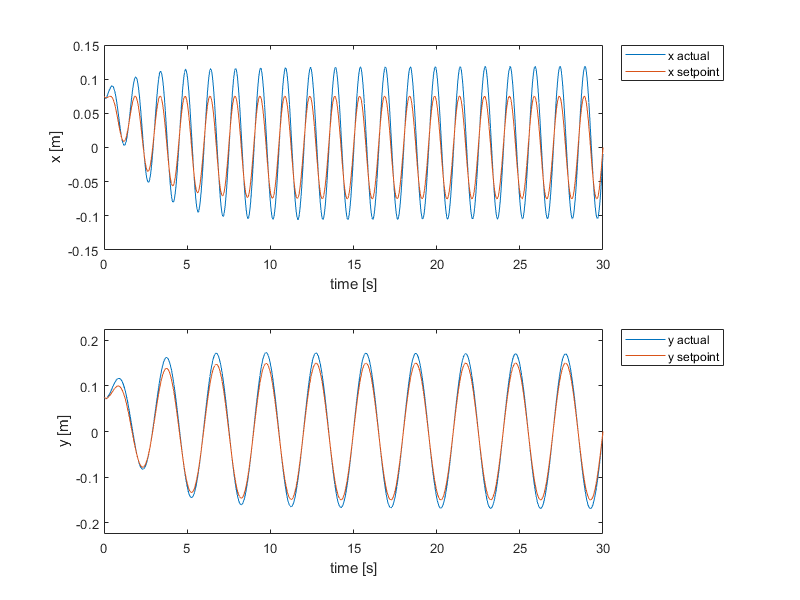

trajs = figure;
trajs.Position = [600 200 800 600];
subplot(2,1,1)
plot(simout_Ang_In_SM.tout,simout_Ang_In_SM.x(:,1), simout_Ang_In_SM.tout,simout_Ang_In_SM.y1_s_vec(:,1)) 
legend('x actual', 'x setpoint', 'Location', 'bestoutside')
xlabel('time [s]')
ylabel('x [m]')

subplot(2,1,2)
plot(simout_Ang_In_SM.tout,simout_Ang_In_SM.x(:,5), simout_Ang_In_SM.tout,simout_Ang_In_SM.y2_s_vec(:,1)) 
ylim([-3*x_0(1) 3*x_0(1)])
xlabel('time [s]')
ylabel('y [m]')
legend('y actual', 'y setpoint', 'Location', 'bestoutside')


angles = figure;

angles =   Figure (44) with properties:

      Number: 44
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [1440 918 560 420]
       Units: 'pixels'

  Show all properties


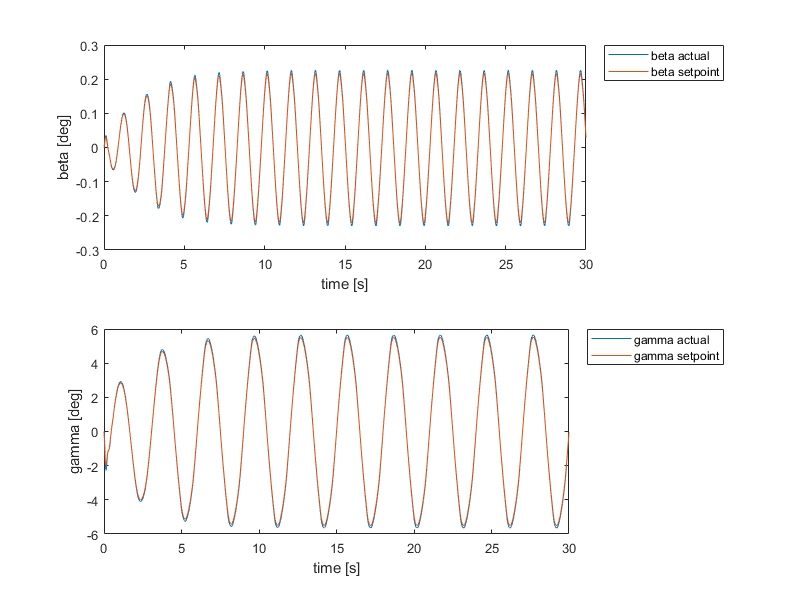

angles.Position = [600 200 800 600];
subplot(2,1,1)
subplot(2,1,1)
plot(simout_Ang_In_SM.tout,simout_Ang_In_SM.ILC_beta(:,2), simout_Ang_In_SM.tout,simout_Ang_In_SM.ILC_beta(:,1)) 
legend('beta actual', 'beta setpoint', 'Location', 'bestoutside')
xlabel('time [s]')
ylabel('beta [deg]')

subplot(2,1,2)
plot(simout_Ang_In_SM.tout,rad2deg(simout_Ang_In_SM.ILC_gamma(:,2)), simout_Ang_In_SM.tout,rad2deg(simout_Ang_In_SM.ILC_gamma(:,1))) 
legend('gamma actual', 'gamma setpoint', 'Location', 'bestoutside')
xlabel('time [s]')
ylabel('gamma [deg]')
legend('gamma actual', 'gamma setpoint')

### Animate Responses

n = 1;
%t_window = 2*pi/omega_sim*d*n; %Print n cycles worth of trajectory history
t_window = 2*omega_sim
frac = 1;
i_plot = round(length(simout_Ang_In_SM.tout)/frac)
Animate_Response(simout_Ang_In_SM.y1(1:i_plot),simout_Ang_In_SM.y1_s_vec(1:i_plot,1),...
    simout_Ang_In_SM.y2(1:i_plot),simout_Ang_In_SM.y2_s_vec(1:i_plot,1),simout_Ang_In_SM.tout(1:i_plot),25,'Ang_in_SM.gif', r_sim, t_window)



% %view_vec = 2;
% % Animate_Response_3D(simout_Ang_In_SM.x,simout_Ang_In_SM.tout,25,'try_3D_tpdwnView.gif',VDefs, view_vec)
view_vec = [140 40];
Animate_Response_3D(simout_Ang_In_SM.x,simout_Ang_In_SM.tout,25,'Ang_in_SM_3D.gif',VDefs, view_vec)